## Pregunta 1 Vegetable Oil

Bartomeu Perello Comas

clear all

index = [1 2 3 4 5 6 7]';
girasol = [14.14 14.11 15.02 16.33 17.42 18.2 19.33]';

Recta

precta = polyfit(index,girasol,1);
rect= polyval(precta,index);

valrecta = polyval(precta,8)

valrecta = 20.1000

Parabola

ppar = polyfit(index,girasol,2);
par = polyval(ppar,index);

valpar = polyval(ppar,8)

valpar = 20.7729

Cubica

pcub = polyfit(index,girasol,3);
cub = polyval(pcub,index);

valcub = polyval(pcub,8)

valcub = 19.4729

Polinomi interpolador

pint= polyfit(index,girasol,6);
inter = polyval(pint,index);

valint = polyval(pint,8)

valint = 22.0500

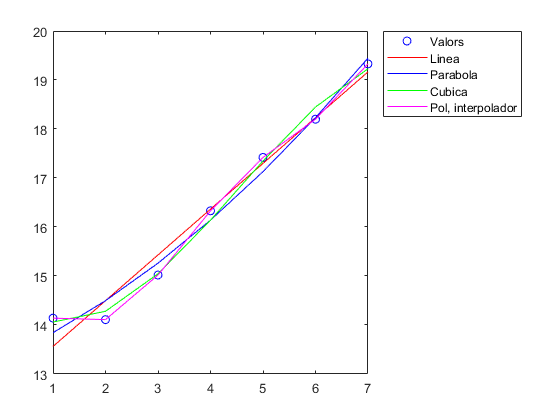

plot(index,girasol,'ob',index,rect,'r',index,par,'b',index,cub,'g',index,inter,'m'), legend('Valors','Linea','Parabola','Cubica','Pol, interpolador','Location','bestoutside')

table(index,girasol,rect,abs(girasol-rect),par,abs(girasol-par),cub,abs(girasol-cub),inter,abs(girasol-inter))

ans = 7×10 table
    index    girasol     rect       Var4       par        Var6       cub        Var8      inter      Var10   
    _____    _______    ______    ________    ______    ________    ______    ________    _____    __________

      1       14.14     13.562      0.5775    13.843     0.29714     14.06    0.080476    14.14    7.1054e-15
      2       14.11     14.496     0.38643    14.496     0.38643     14.28     0.16976    14.11    1.5987e-14
      3       15.02      15.43     0.41036    15.262     0.24214    15.045    0.025476    15.02    8.8818e-15
      4       16.33     16.364    0.034286     16.14        0.19     16.14        0.19    16

## Pregunta 2

El fenomen de runge no es compleix en cap dels casos que he calculat, hem pareixen models correctes el cubic i el polinomi interpolador, el lineal i el parabolic en la meva opinió esbiaixen bastant els resultats, essent el polinomi interpolador el millor de tots ja que l'error en els punts que coneixem es molt baix